clear
tspan = [0 200];

%定常値を設定
%{
judge ok!

安定
steady_delta = [1.1;1.6;1.4];
steady_deltaomega = [0;0;0];
steady_E = [1;2.5;2.1];
% W が単調減少する特異的な error ?
error = [1;1;1;0;0;0;1;1;1];

安定
steady_delta = [-0.2607;0.6415;0.4656];
steady_deltaomega = [0;0;0];
steady_E = [4.3303;3.2225;2.2370];

ぎり安定
steady_delta = [-1.25664;0;0];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

不安定
steady_delta = [0.942478;0;-1.41372];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

めちゃ安定?
steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];
% W が単調減少する error ?
error = [0;0;0;0;0;0;0.1;-0.1;-0.1];
%slack-> error = [0.01;0;0;0;0;0;0.1;-0.1;-0.1];
% steady　誤差小さい -> error = [0;0;0.0001;0;0;0;0.1;-0.1;-0.1];
% steadyだけどすんごい揺れる-> error = [0;0;0.01;0;0;0;0;0;0];

%}

% Ured_G, W_F, Wred_G, W_F + Wred_G のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum = 1;

% diff( W_F + Wred_G ) のグラフを表示するなら 1 . 表示しないなら 0.
flag_accum_diff = 1;

steady_delta = [0.15708;0;-0.15708];
steady_deltaomega = [0;0;0];
steady_E = [3.2225;3.2225;3.2225];

steady_generator_state = [steady_delta; steady_deltaomega; steady_E];

error = [0;0;0.01;0;0;0;0;0;0];

initial_generator_state = steady_generator_state + error;

judge_steady(initial_generator_state)

Matrix: psi is steady.
Matrix: A is steady.
Matrix: B has zero eigenvalue.
Matrix: L has zero eigenvalue.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive definite.


judge_steady(steady_generator_state)

Matrix: psi is steady.
Matrix: A is steady.
Matrix: B has zero eigenvalue.
Matrix: L has zero eigenvalue.
Matrix: Lo=L-C*inv(A)*B　is symmetric positive semi-definite


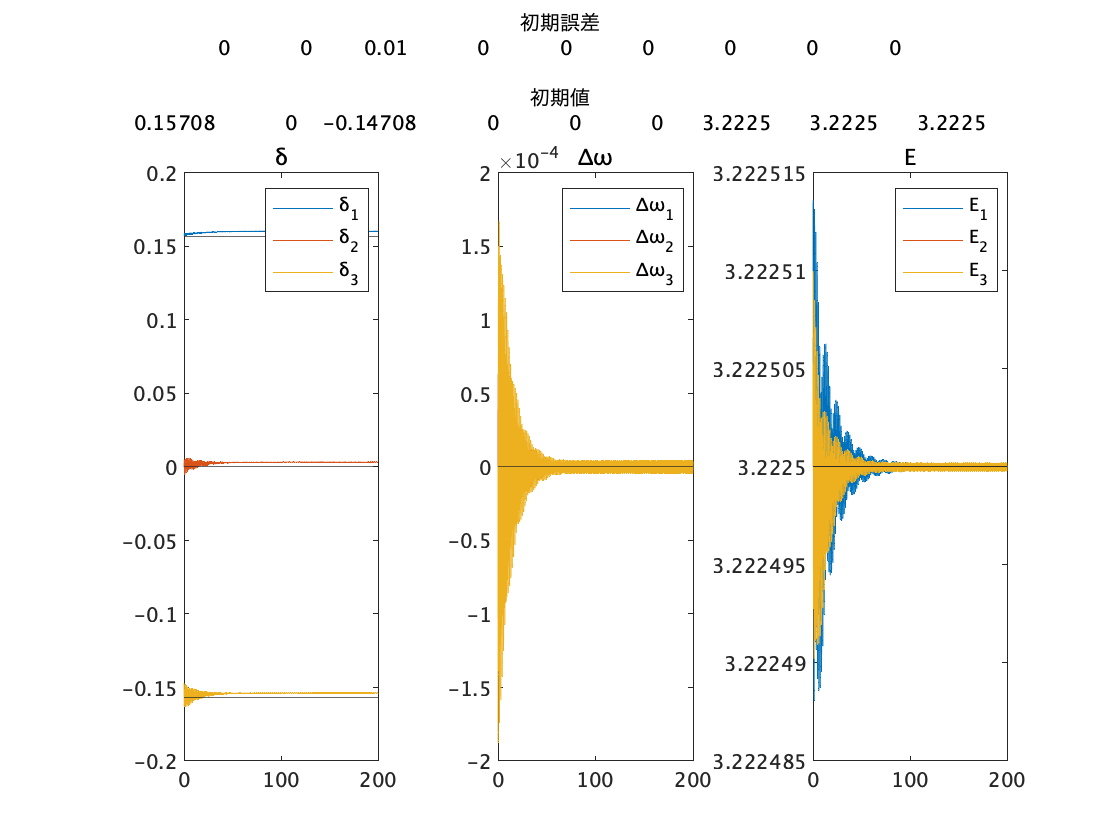

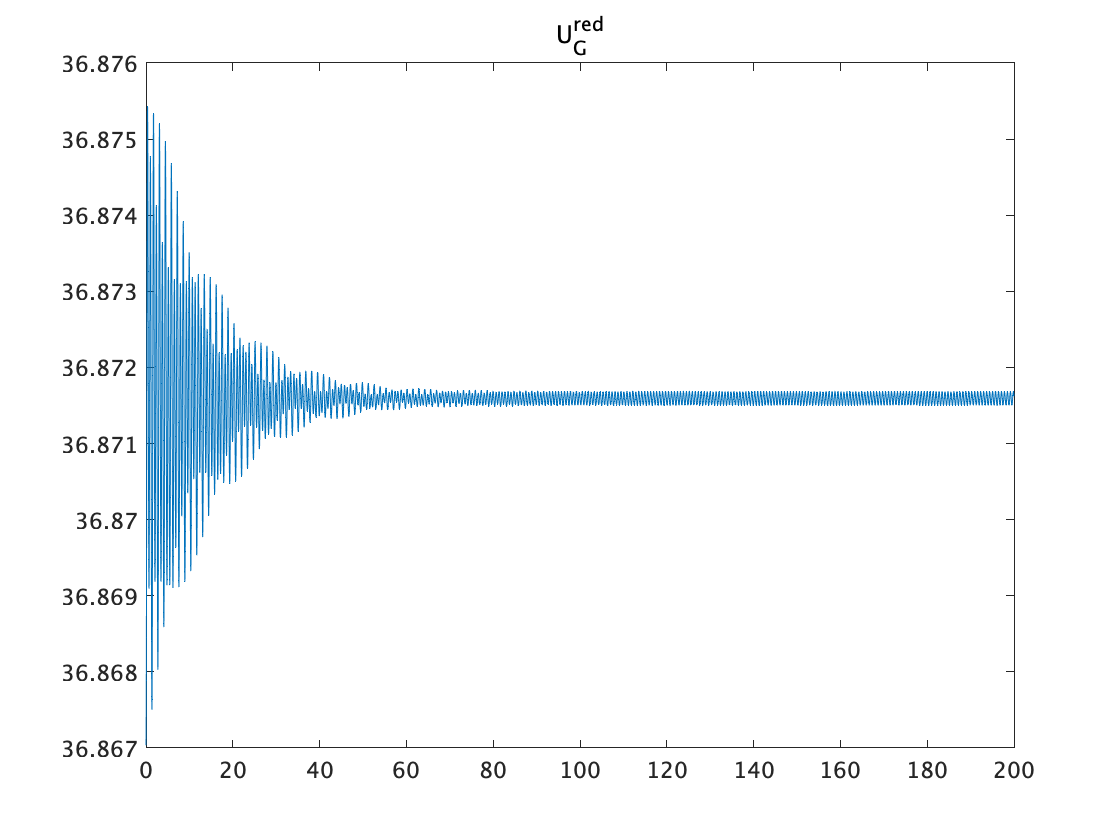

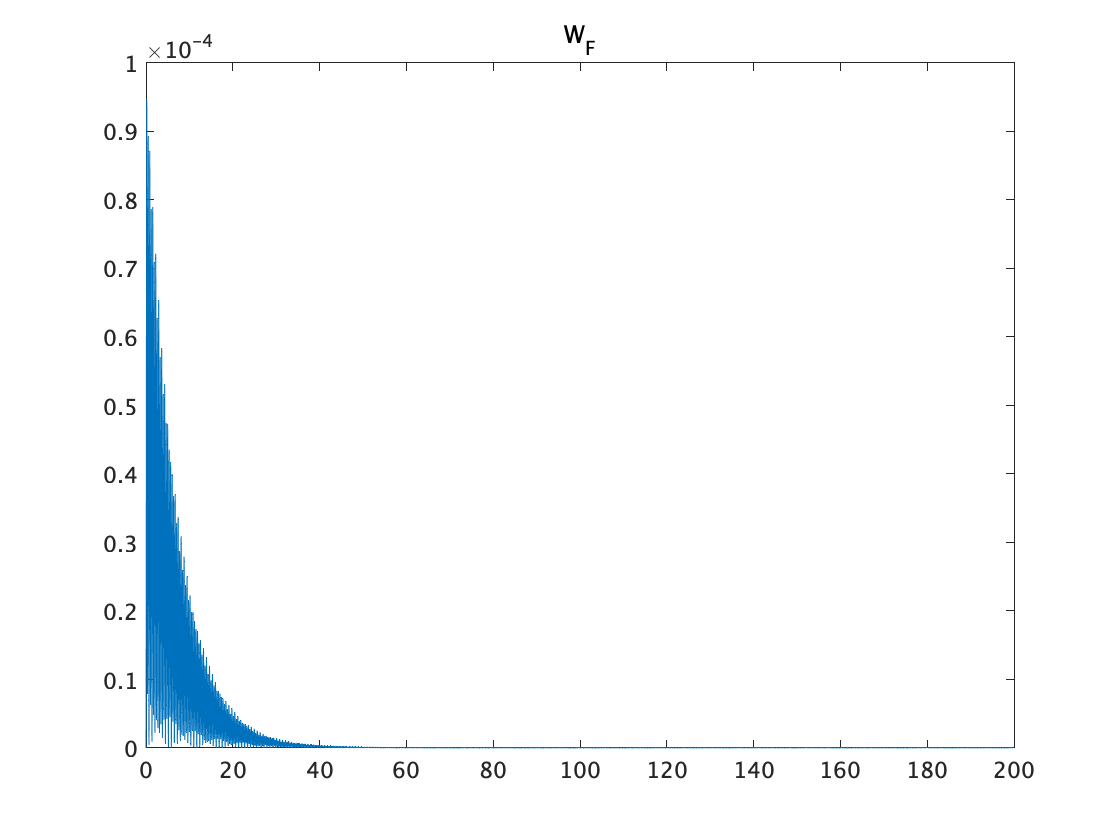

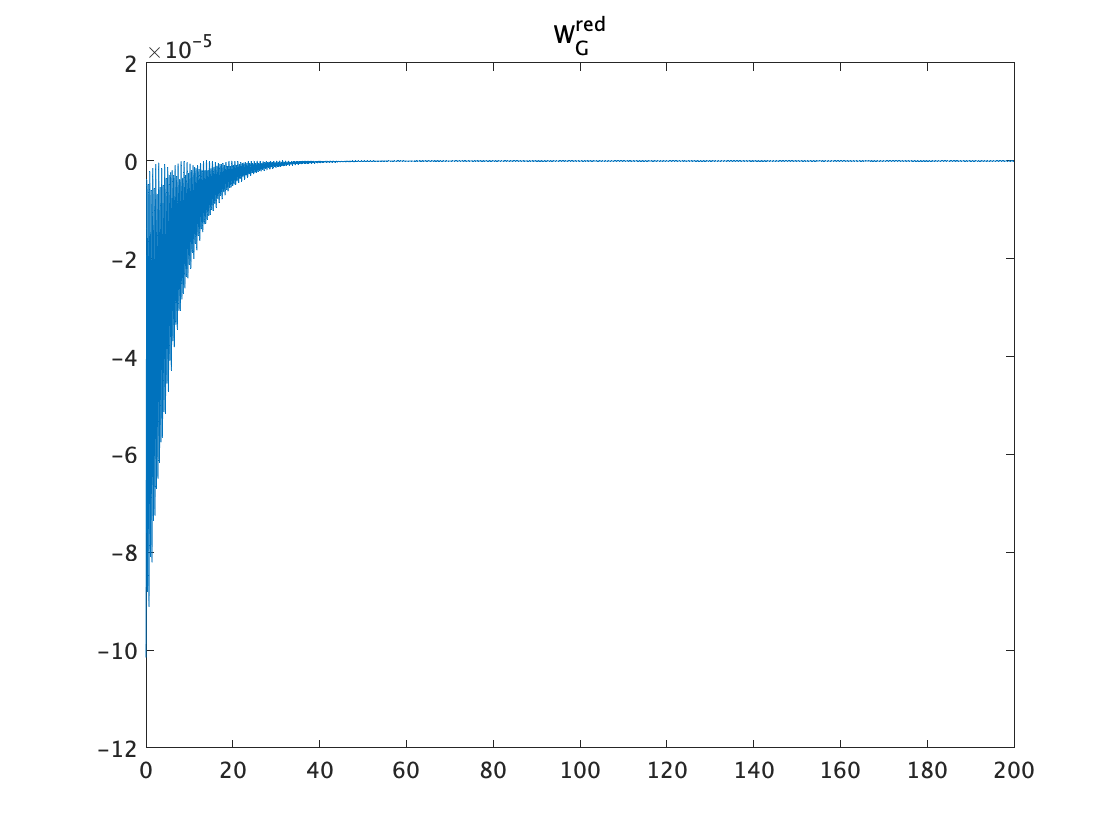

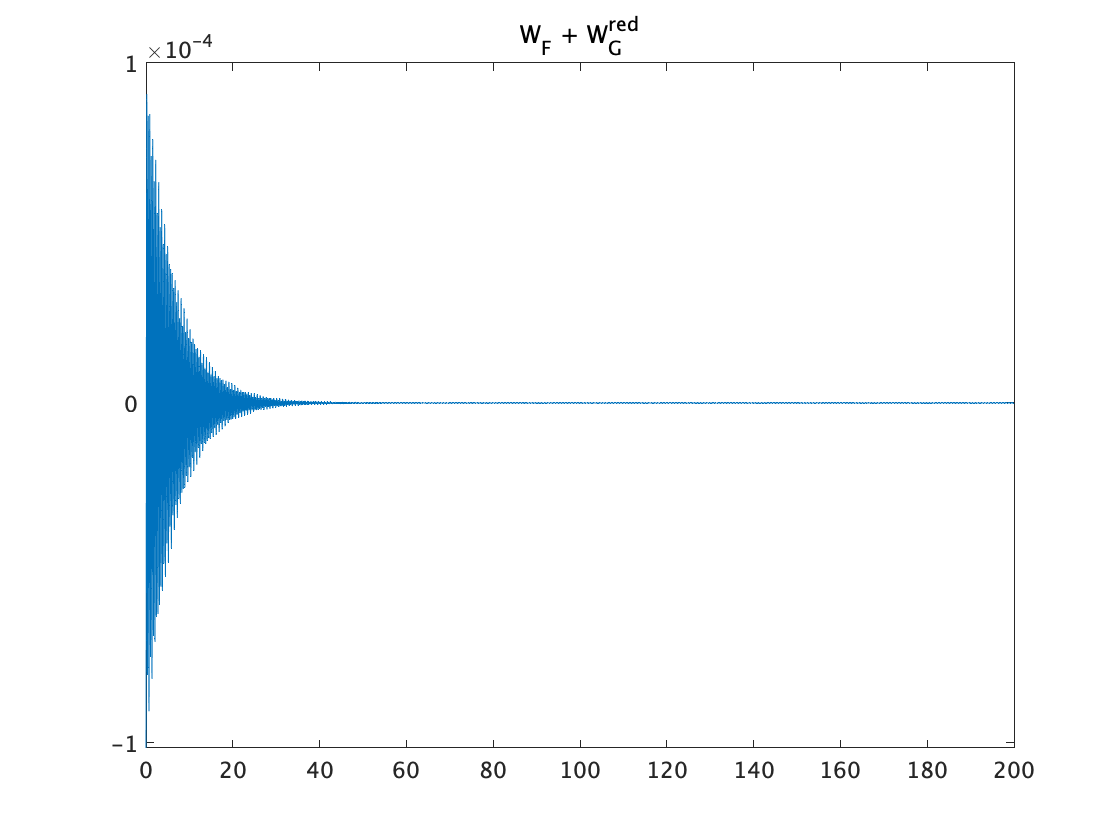

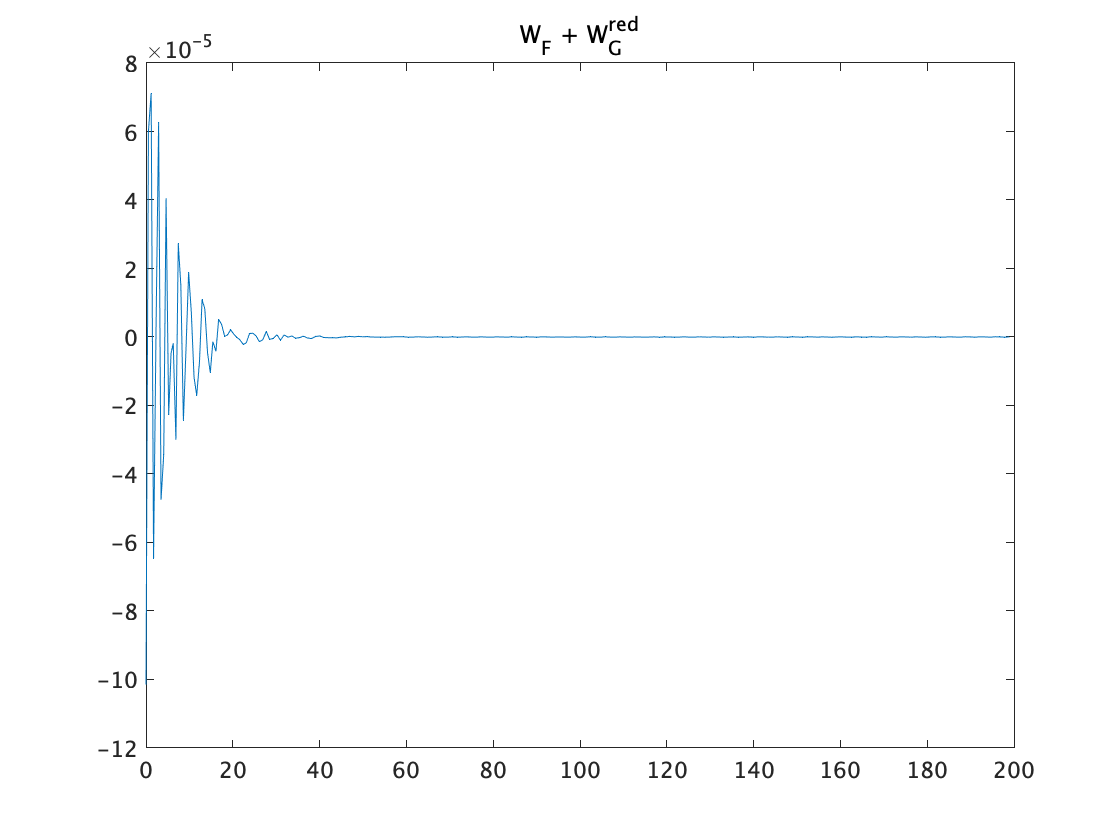

W_FGred_rgh = 	1.0e+-3 *

   -0.1015    0.0600    0.0711   -0.0645    0.0036    0.0627   -0.0475   -0.0342    0.0405   -0.0227   -0.0048   -0.0018   -0.0300    0.0272    0.0151   -0.0244   -0.0038    0.0189    0.0073   -0.0117   -0.0171   -0.0072    0.0110    0.0081   -0.0046   -0.0104   -0.0014   -0.0042    0.0052    0.0037    0.0002    0.0007    0.0021    0.0009   -0.0001   -0.0008   -0.0022   -0.0017    0.0009    0.0012    0.0004   -0.0014   -0.0009    0.0016   -0.0007   -0.0004    0.0007   -0.0009    0.0006   -0.0001


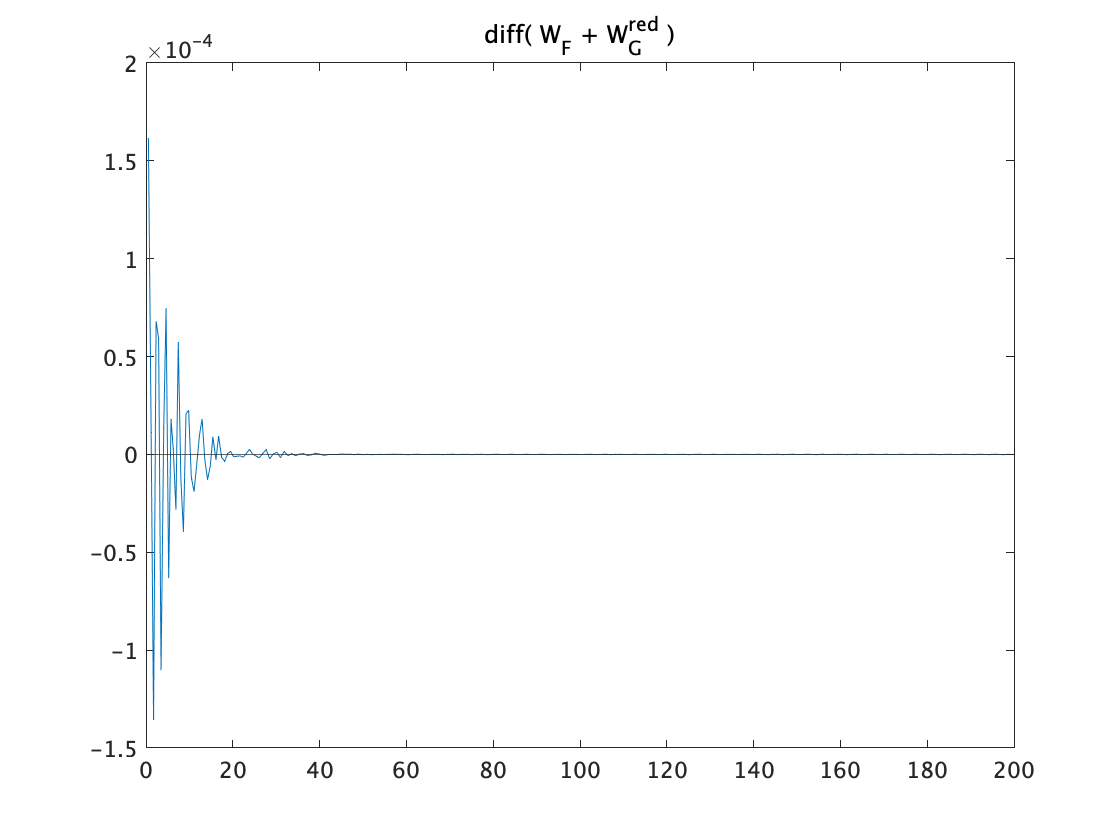

max_diff_W_FGred = 1.6149e-04

dff_W_FGred_rgh = 	1.0e+-3 *

    0.1615    0.0111   -0.1357    0.0681    0.0591   -0.1102    0.0133    0.0747   -0.0632    0.0179    0.0030   -0.0282    0.0572   -0.0122   -0.0395    0.0207    0.0226   -0.0116   -0.0190   -0.0053    0.0099    0.0182   -0.0028   -0.0127   -0.0058    0.0090   -0.0028    0.0093   -0.0015   -0.0035    0.0005    0.0015   -0.0012   -0.0010   -0.0007   -0.0014    0.0004    0.0027    0.0002   -0.0008   -0.0017    0.0005    0.0025   -0.0023    0.0003    0.0011   -0.0016    0.0015   -0.0006    0.0004



plot_generator_state_wrap = @(error,initial_generator_state) plot_generator_state(error,tspan,initial_generator_state,steady_generator_state,flag_accum,flag_accum_diff);

figure;
plot_generator_state_wrap(error,initial_generator_state);



%figure;
%f = fit(t_U(:,1),t_U(:,2),'poly4');
%syms x f1(x) diff2_f1(x)
%f1(x) = f.p1*x^4 + f.p2*x^3 + f.p3*x^2 + f.p4*x + f.p5;
%diff2_f1(x) = diff(f1,2);
%diff2_f1(1:10)  %任意のxで W(x)>=0 
%F = solve(diff2_f1 == 0, x)  %かつ、これが複素数なら蓄積関数WはRealな解を持たなくて、半正定関数

%plot(f,t_U(:,1),t_U(:,2))
